# 2D Inversely designed 1x2 Mode Division Multiplexer

**Photonic inverse-design** uses an end-to-end design philosophy, optimizing the structure to maximize the coupling efficiency between the actual output field and target field. The distribution of relative permittivity, $\varepsilon_r$, of structure, based on gradient-based algorithms, is updated iteratively during the optimization process[1–3]. Photonic inverse-design method can provide unconventional, irregular, counterintuitive structures with previously unattainable functionality, or even higher performance and smaller footprints than traditional devices, which the traditional design method is unable to achieve.

### Step 0: Global settings

The simulation begins with the initialization of a `Model2D` instance, followed by defining the global settings. The working plane is set to the **x-y plane** using the label `'xy'`, which specifies the 2D cross-sectional area for analysis. The simulation operates at a wavelength of **1.55 µm**, commonly used in optical communications. These global settings provide the foundation for defining the geometry and material properties in subsequent steps.

modelMUX = Model2D.initialize();

Model2D: Object Reset and Initialized


modelMUX.setLabel('xy'); % work on x-y plane
modelMUX.setWavelength(1.55e-6); % work at 1.55 um wavelength

### Step 1: Material

The core material is **silicon** while the surrounding cladding is **silicon dioxide**.

eps_core = 3.4712^2; % Silicon (core)
eps_clad = 1.5^2; % Silicon dioxide (cladding)

### Step 2: Input `.gds` and build up device

The width of the input port is 750 nm, and two output ports are 480 nm. The central region has a footprint of 3.63 𝜇m × 3.63 𝜇m.

% SiO2 background box
modelMUX.addDevice(1);
modelMUX.setDevice(1).setGeometry('Rectangle', 8e-6, 8e-6, 'c', [0, 0]);
modelMUX.setDevice(1).setMaterial(eps_clad);

% inverse-designed Si structure
gdspath = getAbsolutePath('.\MUX_21.gds');
modelMUX.addDevice(2);
modelMUX.setDevice(2).setGeometry('GDSII', gdspath);


Library name  : LIB
Creation date : 2025-2-14, 14:16:09
User unit     : 1e-06 m
Database unit : 1e-09 m

Read time  : 00:00:00.266
Structures : 1
Elements   : 1



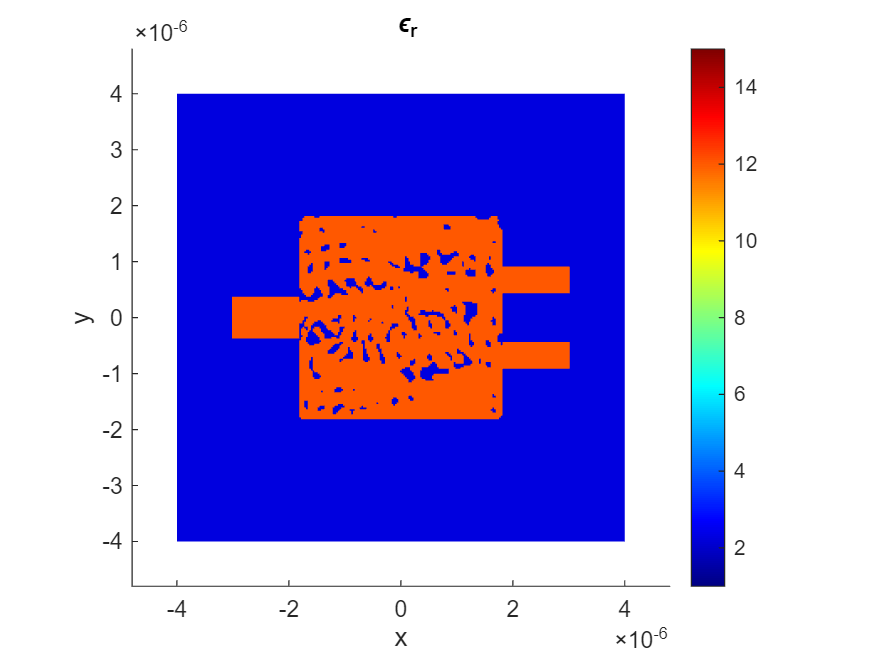

modelMUX.setDevice(2).setMaterial(eps_core);

% assamble and display entire device
modelMUX.assembleDevice;
modelMUX.device.dispImg;

### Step 3: Mesh grid

In our original design code, we defined grids as below. To preserve as many features as possible when converting `.gds` files to MATLAB, we have implemented the same grid structure here.

Nx = 201;
Ny = 201;

dx = 30e-9;
dy = 30e-9;

modelMUX.setMesh([Nx, Ny], [dx, dy]); % the center of coordinates are 0 as default

### Step 4: FDFD solver settings

pml_thickness = [10,10];
modelMUX.setSolver("Scattering", pml_thickness);

###  Step 5: Input port and source

The fundamental and second eigenmodes of input port are injected as source.

modelMUX.addPort('+x', -2.5e-6, [-1e-6, 1e-6]); % unit: m

polarization = 'TE'; % TE mode
num_mode = [1,2]; % fundamental mode

modelMUX.addSource("EigenMode", "ModeType", polarization, "ModeNum", num_mode);

Source has been set and ready to be used.


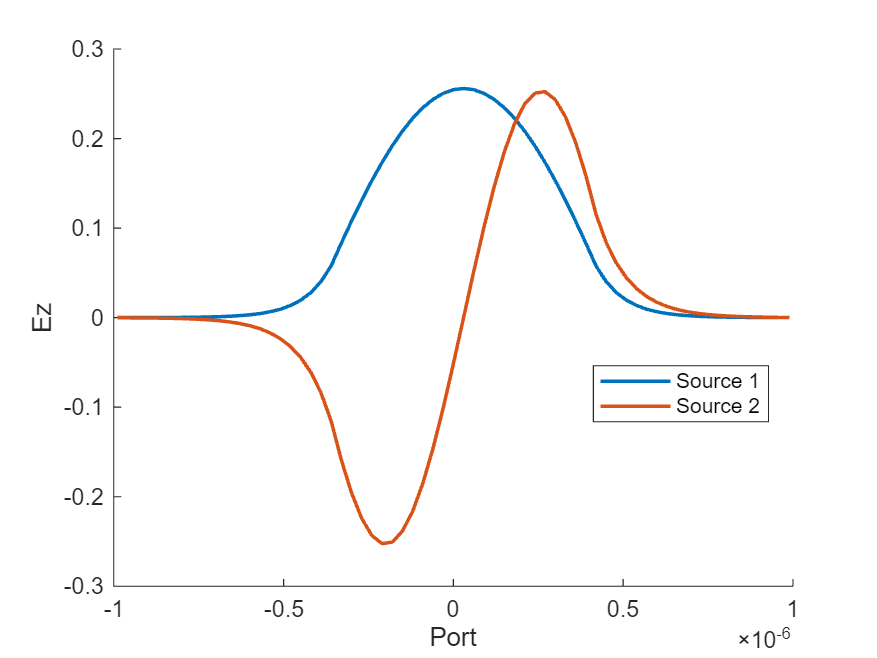

modelMUX.source.dispProfile('Ez');

### Step 6: 2D scattering simulation

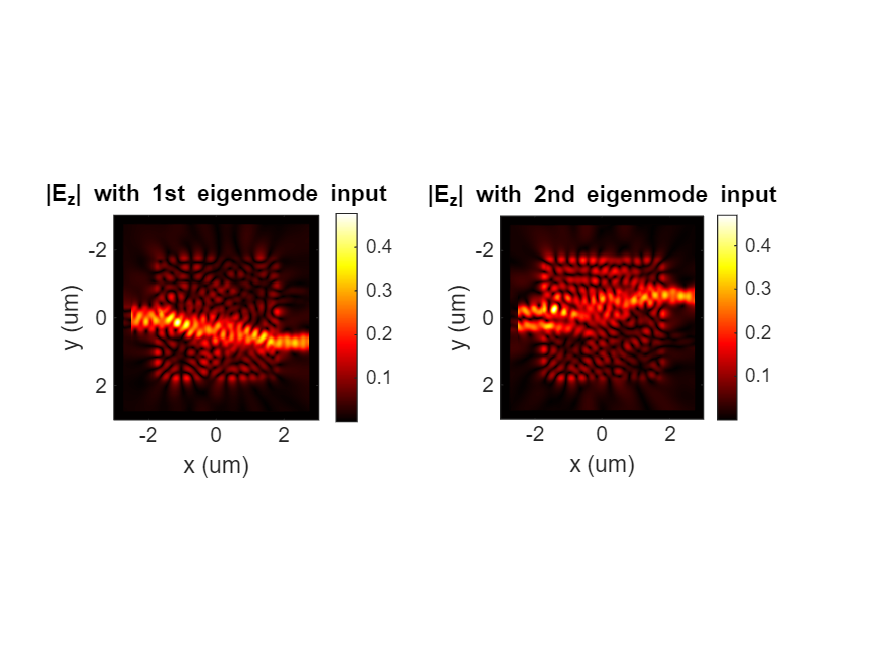

modelMUX.solve;
solution = modelMUX.exportResult;

figure;
subplot(1,2,1);
imagesc(solution.x*1e6, solution.y*1e6, abs(solution.Ez(:,:,1)).');
xlabel('x (um)'), ylabel('y (um)'); axis image;
title('|E_z| with 1st eigenmode input');
colormap hot; colorbar;
subplot(1,2,2);
imagesc(solution.x*1e6, solution.y*1e6, abs(solution.Ez(:,:,2)).');
xlabel('x (um)'), ylabel('y (um)'); axis image;
title('|E_z| with 2nd eigenmode input');
colormap hot; colorbar;

### Reference

[1] Molesky, S., Lin, Z., Piggott, A. Y., Jin, W., Vucković, J., & Rodriguez, A. W. (2018). Inverse design in nanophotonics. *Nature Photonics*, *12*(11), 659-670. 

[2] Piggott, A. Y., Lu, J., Lagoudakis, K. G., Petykiewicz, J., Babinec, T. M., & Vučković, J. (2015). Inverse design and demonstration of a compact and broadband on-chip wavelength demultiplexer. *Nature photonics*, *9*(6), 374-377.

[3] Su, L., Vercruysse, D., Skarda, J., Sapra, N. V., Petykiewicz, J. A., & Vučković, J. (2020). Nanophotonic inverse design with SPINS: Software architecture and practical considerations. *Applied Physics Reviews*, *7*(1).

% Help function
function abspath = getAbsolutePath(relativepath)
    abspath = fullfile(pwd, relativepath);
end